Found 4 images in C:\Users\nagai\Downloads\images
Results -> C:\Users\nagai\Downloads\predictions



Image 1/4: hi.jpg | Area=71526.0 px^2, Major=643.3 px, Minor=248.5 px, Centroid=(231.9,121.9)
Image 2/4: images (2).jpg | Area=90892.0 px^2, Major=619.2 px, Minor=256.7 px, Centroid=(573.6,493.4)
Image 3/4: images.jpg | Area=418172.0 px^2, Major=1011.7 px, Minor=741.6 px, Centroid=(1410.2,968.7)
Image 4/4: img.jpg | Area=52413.0 px^2, Major=338.6 px, Minor=213.2 px, Centroid=(299.1,260.5)


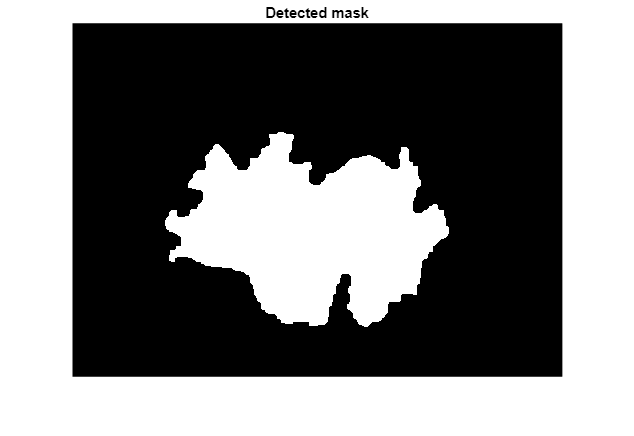

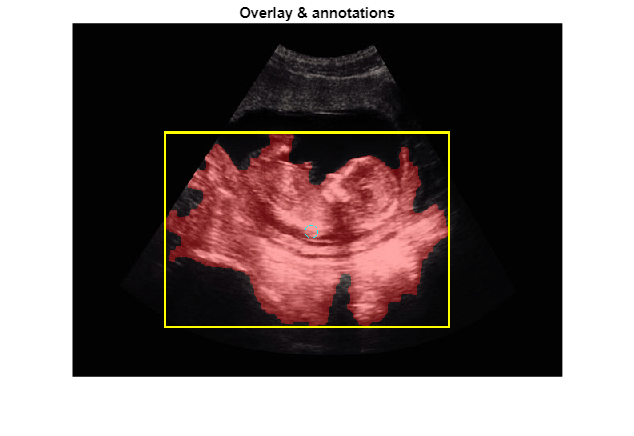

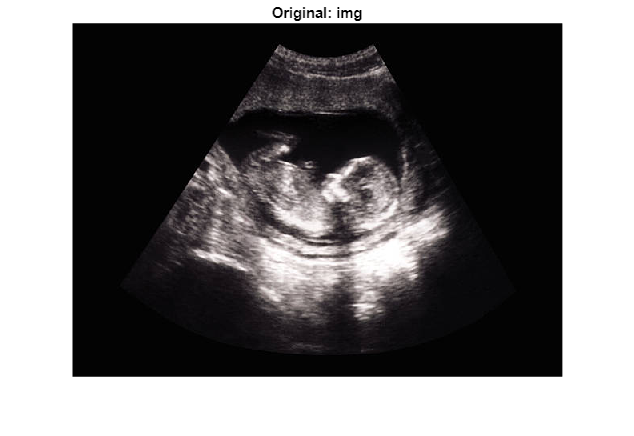

Processing done. Annotated files saved to: C:\Users\nagai\Downloads\predictions


% ultrasound_fetus_detect_and_measure_fixed.m
% Read ultrasound images from a folder, segment the largest object (fetus candidate),
% compute size/position measures, overlay highlights, and save annotated images.
%
% NOTE: baseline classical image-processing approach (not clinical-grade).
% Edit dataDir and pix2mm at top.

clear; close all; clc;

%% -------------------- USER SETTINGS --------------------
dataDir = 'C:\Users\nagai\Downloads\images';  % <-- set this to your folder of ultrasound images
outDir  = fullfile(fileparts(dataDir), 'predictions'); % results saved here (auto-create)
pix2mm  = [];    % set e.g. 0.25 if you know mm-per-pixel, otherwise leave empty
minObjectAreaPx = 500; % minimum area to consider a connected object (tune for your data)
verbose = true;  % show figures while processing (set false for batch mode)

%% -------------------- INPUT FILE LIST --------------------
if ~isfolder(dataDir)
    error('dataDir does not exist: %s', dataDir);
end

% gather image files with common extensions
exts = {'*.png','*.jpg','*.jpeg','*.tif','*.tiff','*.bmp'};
imgFiles = {};
for e = 1:numel(exts)
    d = dir(fullfile(dataDir, exts{e}));
    if ~isempty(d)
        imgFiles = [imgFiles; fullfile({d.folder}', {d.name}')]; %#ok<AGROW>
    end
end
imgFiles = sort(imgFiles);
nFiles = numel(imgFiles);
if nFiles == 0
    error('No image files found in %s', dataDir);
end

% ensure output dir exists
if ~isfolder(outDir)
    mkdir(outDir);
end
fprintf('Found %d images in %s\nResults -> %s\n\n', nFiles, dataDir, outDir);

%% -------------------- PROCESS IMAGES --------------------
for idx = 1:nFiles
    infile = imgFiles{idx};
    [~, basename, ext] = fileparts(infile);
    try
        Iorig = imread(infile);
    catch ME
        warning('Could not read %s: %s. Skipping.', infile, ME.message);
        continue;
    end

    % convert to grayscale if RGB
    if ndims(Iorig) == 3
        Igray = rgb2gray(Iorig);
    else
        Igray = Iorig;
    end

    % Preprocessing: contrast enhancement & denoise (typical for ultrasound)
    Iad = adapthisteq(Igray);        % CLAHE
    Ifilt = medfilt2(Iad, [3 3]);    % remove small speckle
    Ifilt = imgaussfilt(Ifilt, 1);   % smooth

    % Thresholding: Otsu
    lvl = graythresh(Ifilt);
    bw = imbinarize(Ifilt, lvl);

    % Heuristic inversion: ensure foreground is not majority background
    if mean(bw(:)) > 0.5
        bw = ~bw;
    end

    % Morphological cleanup
    bw = imopen(bw, strel('disk', 3));
    bw = imclose(bw, strel('disk', 7));
    bw = imfill(bw, 'holes');

    % Remove small objects
    bw = bwareaopen(bw, minObjectAreaPx);

    % Connected components and choose largest as fetal candidate
    cc = bwconncomp(bw);
    stats = regionprops(cc, 'Area', 'BoundingBox', 'Centroid', 'MajorAxisLength', 'MinorAxisLength', 'Perimeter');
    if isempty(stats)
        warning('No candidate object found in %s', basename);
        % save original image to out folder with note
        try
            outImg = insertText(Iorig, [10 10], 'No object found', 'FontSize',18,'BoxColor','red','BoxOpacity',0.6);
            imwrite(outImg, fullfile(outDir, [basename '_noobj' ext]));
        catch
            imwrite(Iorig, fullfile(outDir, [basename '_noobj' ext]));
        end
        continue;
    end
    areas = [stats.Area];
    [~, idxMax] = max(areas);
    obj = stats(idxMax);

    % Create mask of chosen object
    mask = false(size(bw));
    mask(cc.PixelIdxList{idxMax}) = true;

    % Compute derived measures
    area_px = obj.Area;
    major_px = obj.MajorAxisLength;
    minor_px = obj.MinorAxisLength;
    perimeter_px = obj.Perimeter;
    % Approximate circumference (Ramanujan)
    a = major_px/2; b = minor_px/2;
    if a>0 && b>0
        circ_px = pi*(3*(a+b) - sqrt((3*a + b)*(a + 3*b)));
    else
        circ_px = NaN;
    end

    if ~isempty(pix2mm)
        area_mm2 = area_px * (pix2mm^2);
        major_mm = major_px * pix2mm;
        minor_mm = minor_px * pix2mm;
        circ_mm = circ_px * pix2mm;
        unitStr = 'mm';
    else
        area_mm2 = area_px;
        major_mm = major_px;
        minor_mm = minor_px;
        circ_mm = circ_px;
        unitStr = 'px';
    end

    % Centroid and bounding box
    centroid = obj.Centroid;
    bbox = obj.BoundingBox; % [x y w h]

    % --- build overlay safely ---
    % Ensure original image is RGB uint8
    if ndims(Iorig) == 2
        Icolor = repmat(Iorig, [1 1 3]); % grayscale -> RGB
    else
        Icolor = Iorig;
    end
    % convert to double for blending
    Idouble = double(Icolor);

    % make a uint8 mask image of same size (0..255)
    mask_u8 = uint8(mask) * 255;              % size: [H W]
    mask3 = repmat(mask_u8, [1 1 3]);         % size: [H W 3]

    alpha = 0.35;                             % overlay opacity
    % blend on red channel (for visibility)
    overlay_double = Idouble;
    overlay_double(:,:,1) = (1-alpha)*Idouble(:,:,1) + alpha*double(mask3(:,:,1));
    overlay_double(:,:,2) = (1-alpha)*Idouble(:,:,2) + alpha*0; % keep G low where mask
    overlay_double(:,:,3) = (1-alpha)*Idouble(:,:,3) + alpha*0; % keep B low where mask

    overlay = uint8(overlay_double);

    % draw bounding box and centroid (insertShape/insertMarker expect RGB uint8)
    boxPos = [bbox(1), bbox(2), bbox(3), bbox(4)];
    try
        overlay = insertShape(overlay, 'Rectangle', boxPos, 'Color','yellow','LineWidth',3);
        overlay = insertMarker(overlay, centroid, 'o', 'Color','cyan','Size',8);
    catch
        % If Computer Vision Toolbox not available, draw simple rectangle/marker
        overlay = drawrectanglefallback(overlay, boxPos);
        overlay = drawmarkerfallback(overlay, centroid);
    end

    % text annotation
    txt = {sprintf('Area: %.1f %s^2', area_mm2, unitStr), ...
           sprintf('Major: %.1f %s', major_mm, unitStr), ...
           sprintf('Minor: %.1f %s', minor_mm, unitStr)};
    try
        overlay = insertText(overlay, [10 10], txt, 'FontSize',14, 'BoxColor','black','BoxOpacity',0.6,'TextColor','white');
    catch
        % fallback: do nothing if insertText isn't available
    end

    % show results optionally
    if verbose
        figure(1); imshow(Iorig); title(['Original: ' basename], 'Interpreter','none');
        
grid on
        figure(2); imshow(mask); title('Detected mask');
        figure(3); imshow(overlay); title('Overlay & annotations');
        drawnow;
    end

    % save annotated image
    outName = fullfile(outDir, [basename '_annot' ext]);
    imwrite(overlay, outName);

    % print summary
    fprintf('Image %d/%d: %s | Area=%.1f %s^2, Major=%.1f %s, Minor=%.1f %s, Centroid=(%.1f,%.1f)\n', ...
        idx, nFiles, [basename ext], area_mm2, unitStr, major_mm, unitStr, minor_mm, unitStr, centroid(1), centroid(2));
end

fprintf('Processing done. Annotated files saved to: %s\n', outDir);

%% ---------------------- helper fallbacks ----------------------
function out = drawrectanglefallback(img, boxPos)
% draws a simple rectangle by painting pixels (fallback if insertShape missing)
out = img;
x = round(boxPos(1)); y = round(boxPos(2)); w = round(boxPos(3)); h = round(boxPos(4));
[H,W,~] = size(img);
x1 = max(1,x); y1 = max(1,y); x2 = min(W,x+w); y2 = min(H,y+h);
th = 3; % thickness
for t = 0:th-1
    xi1 = max(1, x1+t); yi1 = max(1, y1+t); xi2 = min(W, x2-t); yi2 = min(H, y2-t);
    out(yi1:yi1, xi1:xi2, 1) = 255; % top
    out(yi2:yi2, xi1:xi2, 1) = 255; % bottom
    out(yi1:yi2, xi1:xi1, 1) = 255; % left
    out(yi1:yi2, xi2:xi2, 1) = 255; % right
end
end

function out = drawmarkerfallback(img, centroid)
out = img;
[H,W,~] = size(img);
cx = round(centroid(1)); cy = round(centroid(2));
if cx < 1 || cx > W || cy < 1 || cy > H, return; end
s = 6;
x1 = max(1, cx-s); x2 = min(W, cx+s);
y1 = max(1, cy-s); y2 = min(H, cy+s);
out(y1:y2, cx, 3) = 255; % vertical line in blue
out(cy, x1:x2, 3) = 255; % horizontal line
end
